# Asset Allocation Project - Computational Finance

## Data loading

We clear our workspace, add the needed functions to the path and load the data as tables from the excel files.

% clear workspace

clear all
close all
clc
warning('off', 'all');

% add the functions to the path
addpath('functions/');

% load data as tables
data_dir = "data/";
table_prices = readtable(data_dir + "prices_fin.xlsx");
table_sector = readtable(data_dir + "sectors_fin.xlsx", "TextType", "string");
table_cap = readtable(data_dir + "market_cap_fin.xlsx", "TextType", "string");

## Transform data from tables to timetables

First of all, we need to transform our data into easily accessible arrays and save some useful variables to be used down the line.

dates = table_prices(:, 1).Variables; % dates
values = table_prices(:, 2:end).Variables; % prices
cap = table_cap.MarketCap;
names_assets = table_prices.Properties.VariableNames(2:end); % names of assets
N_assets = size(values, 2);
N_portfolios = 100; % number of portfolios to simulate
timetable_prices = array2timetable(values, 'RowTimes', dates, 'VariableNames', names_assets);

## Part A

For the first part of the analysis, prices for the dates ranging from 11/05/2021 to 11/05/2022 were considered. For these dates we computed the logarithmic returns, their expected value and their variance-covariance matrix.

start_date_A = datetime('11/05/2021', 'InputFormat', 'dd/MM/yyyy');
end_date_A = datetime('11/05/2022', 'InputFormat', 'dd/MM/yyyy');
dates_range_A = timerange(start_date_A, end_date_A, "closed"); % range of dates
subsample_A = timetable_prices(dates_range_A, :);
array_assets_A = subsample_A.Variables; % array of prices
Ret_array_A = array_assets_A(2:end, :)./array_assets_A(1:end-1, :)-1; % linear returns
LogRet_array_A = log(array_assets_A(2:end, :)./array_assets_A(1:end-1, :)); % array of log returns
ExpLogRet_A = mean(LogRet_array_A); % expected log returns
CovMatRet_A = cov(LogRet_array_A); % covariance matrix of log returns

## Exercise 1: Efficient frontier with standard constraints

We compute the efficient frontier under the standard constraints, i.e. all weights sum up to one, and there is no shortselling. 

pStandard = Portfolio('AssetList', names_assets); % create portfolio object
pStandard = setAssetMoments(pStandard, ExpLogRet_A, CovMatRet_A); % set moments of the portfolio

% use standard constraints: sum(w) = 1, 0 <= w_i <= 1
% all weights sum  to 1, no shorting, 100% invested
pStandard = setDefaultConstraints(pStandard);
pStandard = setBounds(pStandard, zeros(N_assets, 1), ones(N_assets, 1));

pwgt = estimateFrontier(pStandard, N_portfolios); % estimate frontier using 100 points

[pf_risk, pf_ret] = estimatePortMoments(pStandard, pwgt); % estimate moments of the frontier

## Plot efficient frontier

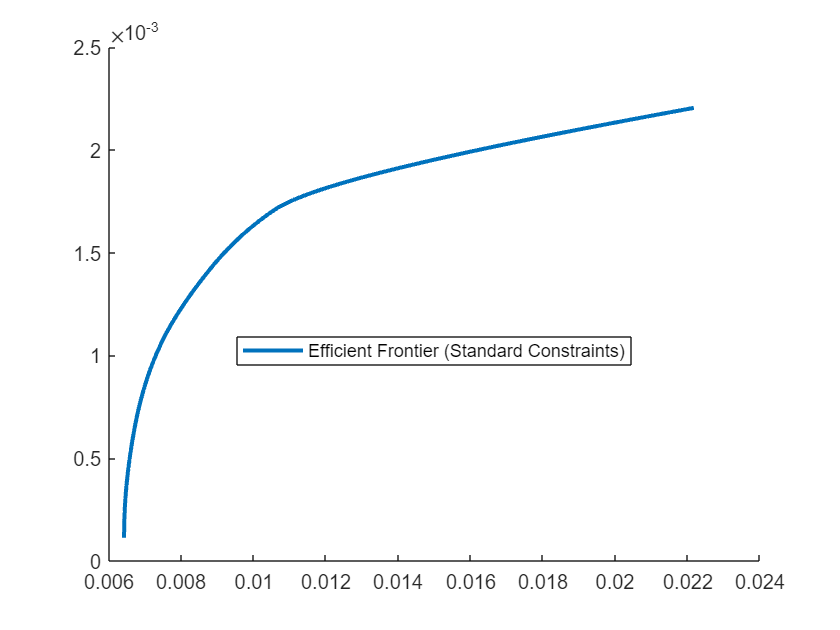

figure % create new figure
hold on
plot_legend = legend('Location', 'best'); % add legend and keep its handle

plot(pf_risk, pf_ret, 'LineWidth', 2); % plot frontier
% add the frontier to the legend
plot_legend.String{end} = "Efficient Frontier (Standard Constraints)";

## Minimum variance portfolio

This is the minimum variance portfolio on the efficient frontier with standard constraints. This portfolio will be named **Portfolio A**.

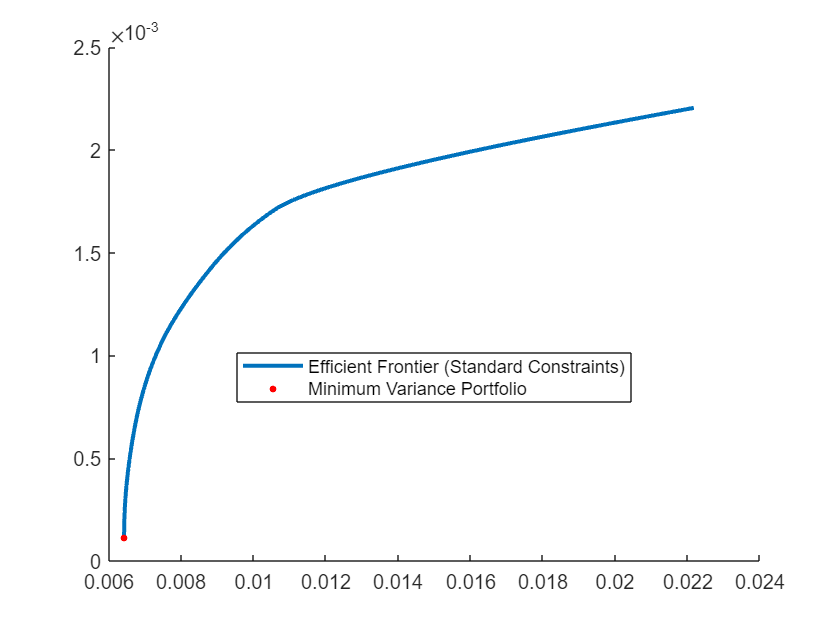

[~, min_var_idx] = min(pf_risk);
portfolioA = pwgt(:,min_var_idx); % weights of the minimum variance portfolio

% plot minimum variance portfolio
plot(pf_risk(min_var_idx), pf_ret(min_var_idx), 'r.', 'MarkerSize', 10);
plot_legend.String{end} = "Minimum Variance Portfolio";

## Maximum Sharpe Ratio portfolio

We computed the Sharpe Ratio with risk-free rate equal to zero on the whole frontier and then found the portfolio with the maximum Sharpe Ratio. This portfolio will be named **Portfolio B**.

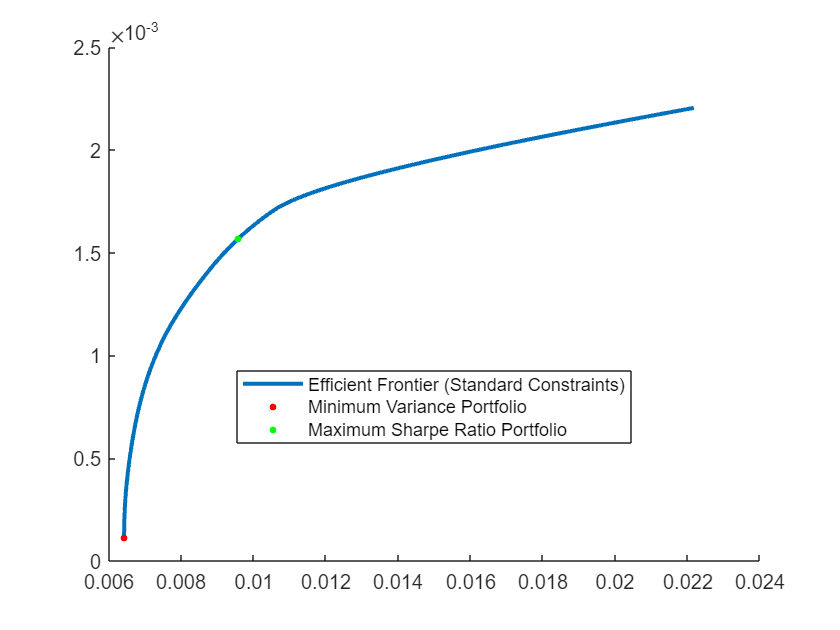

[~, max_sharpe_idx] = max(pf_ret./pf_risk);
portfolioB = pwgt(:,max_sharpe_idx); % weights of the maximum Sharpe Ratio portfolio

% plot maximum Sharpe Ratio portfolio
plot(pf_risk(max_sharpe_idx), pf_ret(max_sharpe_idx), 'g.', 'MarkerSize', 10);
plot_legend.String{end} = "Maximum Sharpe Ratio Portfolio";

## Exercise 2: Efficient frontier with sector constraints

In this exercise three additional constraints were introduced:

- one on the sector 'Consumer Discretionary'

- one on the sector 'Industrials'

- one on all companies in sectors with less than 5 companies.

% set sector constraints

% overall exposure to sector 'Consumer Discretionary' must be greater than 15%
groupMatrix_CD = (table_sector.Sector == "Consumer Discretionary")';
exposure_CD = 0.15;
pConstrained = addGroups(pStandard, groupMatrix_CD, exposure_CD);

% overall exposure to sector 'Industrials' must be lower than 5%
groupMatrix_Ind = (table_sector.Sector == "Industrials")';
exposure_Ind = 0.05;
pConstrained = addGroups(pConstrained, groupMatrix_Ind, [], exposure_Ind);

% weights of sector with less than 5 stocks must be zero
groupCounts_Sector = groupcounts(table_sector, "Sector");
small_sectors = groupCounts_Sector(groupCounts_Sector.GroupCount < 5, :);
small_sectors = (ismember(table_sector.Sector, small_sectors.Sector));
% the actual group matrix is only the corresponding rows of the identity
groupMatrix_Small = eye(N_assets);
groupMatrix_Small = groupMatrix_Small(small_sectors, :);

pConstrained = addGroups(pConstrained, groupMatrix_Small, 0, 0);

## Compute the efficient frontier with sector constraints

pwgt_Constrained = estimateFrontier(pConstrained, N_portfolios); % estimate frontier using 100 points
[pf_risk_Constrained, pf_ret_Constrained] = estimatePortMoments(pConstrained, pwgt_Constrained); % estimate moments of the frontier

## Plot efficient frontier

We plotted the new constrained frontier against the standard frontier, and found it to be, as expected, smaller than the original one.

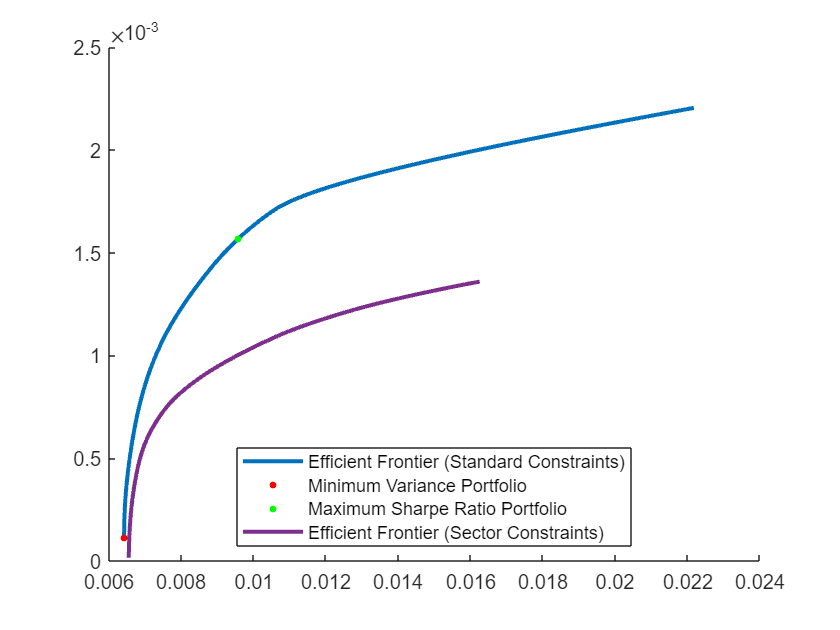

plot(pf_risk_Constrained, pf_ret_Constrained, 'LineWidth', 2); % plot frontier
plot_legend.String{end} = "Efficient Frontier (Sector Constraints)";

## Minimum variance portfolio

Just like for the standard frontier we found the minimum variance portfolio. This portfolio was named **Portfolio C**.

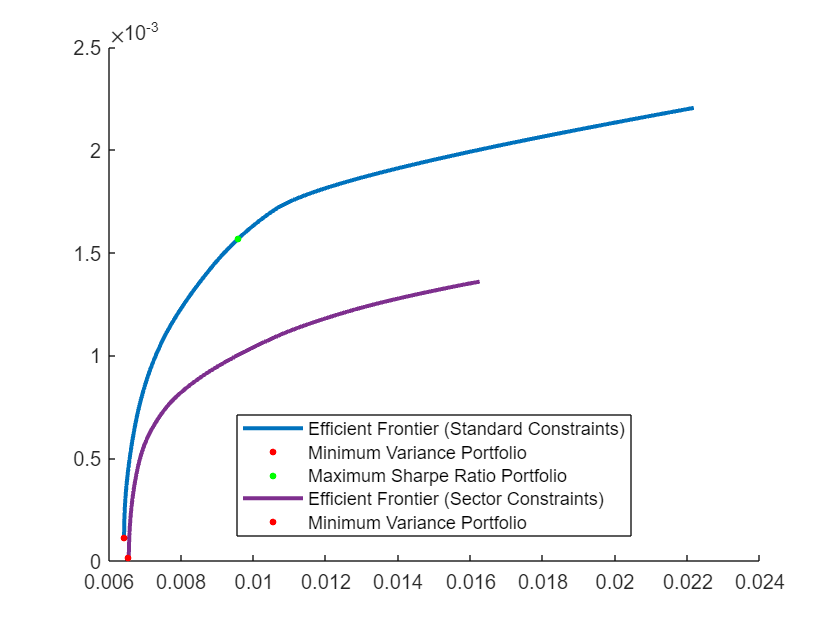

[~, min_var_idx_Constrained] = min(pf_risk_Constrained);
portfolioC = pwgt_Constrained(:,min_var_idx_Constrained); % weights of the minimum variance portfolio

% plot minimum variance portfolio
plot(pf_risk_Constrained(min_var_idx_Constrained), pf_ret_Constrained(min_var_idx_Constrained), 'r.', 'MarkerSize', 10);
plot_legend.String{end} = "Minimum Variance Portfolio";

## Maximum Sharpe Ratio portfolio

The maximum Sharpe ratio portfolio on the constrained frontier was named **Portfolio D**.

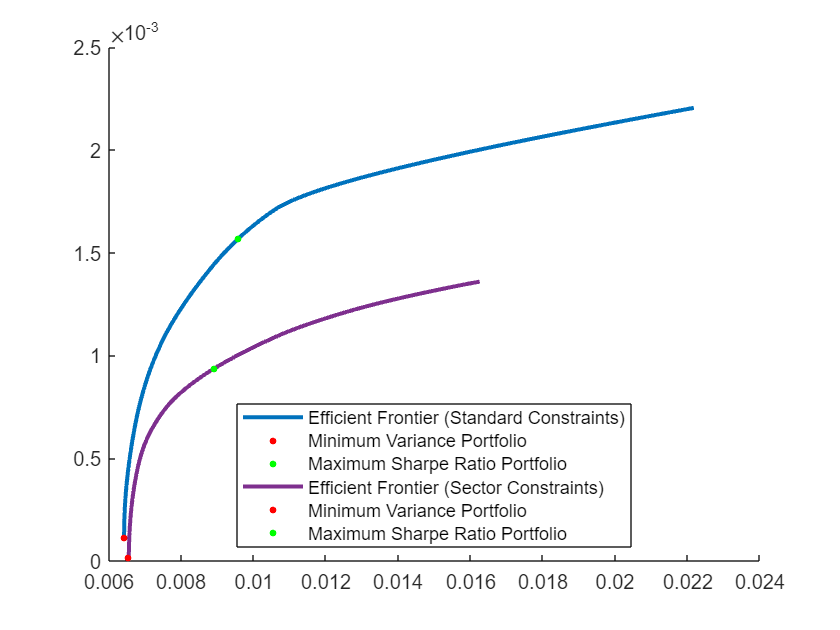

[~, max_sharpe_idx_Constrained] = max(pf_ret_Constrained./pf_risk_Constrained);
portfolioD = pwgt_Constrained(:, max_sharpe_idx_Constrained); % weights of the maximum Sharpe Ratio portfolio

% plot maximum Sharpe Ratio portfolio
plot(pf_risk_Constrained(max_sharpe_idx_Constrained), pf_ret_Constrained(max_sharpe_idx_Constrained), 'g.', 'MarkerSize', 10);
plot_legend.String{end} = "Maximum Sharpe Ratio Portfolio";

## Exercise 3: Robust frontiers with resampling method

We simulated *N_sim=50* frontiers as in exercise 1 and 2 using the resampling method to obtain 2 robust frontiers.

N_sim = 50; % number of simulations

% save the simulation results
pf_risk_sim_standard = zeros(N_portfolios, N_sim);
pf_ret_sim_standard = zeros(N_portfolios, N_sim);
pf_risk_sim_constrained = zeros(N_portfolios, N_sim);
pf_ret_sim_constrained = zeros(N_portfolios, N_sim);

% simulation loop
for n = 1:N_sim
    % sample returns as multivariate normal of mean and covariance of the
    % sample
    R = mvnrnd(ExpLogRet_A, CovMatRet_A, length(LogRet_array_A));
    % create portfolio objects
    pSimulationStandard = setAssetMoments(pStandard, mean(R), cov(R));
    pSimulationConstrained = setAssetMoments(pConstrained, mean(R), cov(R));
    % estimate frontiers
    pwgt_SimulationStandard = estimateFrontier(pSimulationStandard, N_portfolios);
    pwgt_SimulationConstrained = estimateFrontier(pSimulationConstrained, N_portfolios);
    % estimate moments of the frontiers and save
    [pf_risk_sim_standard(:, n), pf_ret_sim_standard(:, n)] = ...
        estimatePortMoments(pSimulationStandard, pwgt_SimulationStandard);
    [pf_risk_sim_constrained(:, n), pf_ret_sim_constrained(:, n)] = ...
        estimatePortMoments(pSimulationConstrained, pwgt_SimulationConstrained);
end

## Compute the robust efficient frontier

Finally we computed the robust frontiers as the mean of the simulated frontiers

% the efficient frontier is the mean of the simulated frontiers
robustFrontier_risk_standard = mean(pf_risk_sim_standard, 2);
robustFrontier_ret_standard = mean(pf_ret_sim_standard, 2);

robustFrontier_risk_constrained = mean(pf_risk_sim_constrained, 2);
robustFrontier_ret_constrained = mean(pf_ret_sim_constrained, 2);

## Plot robust efficient frontier

We plotted the robust frontiers and found them to behave much better.

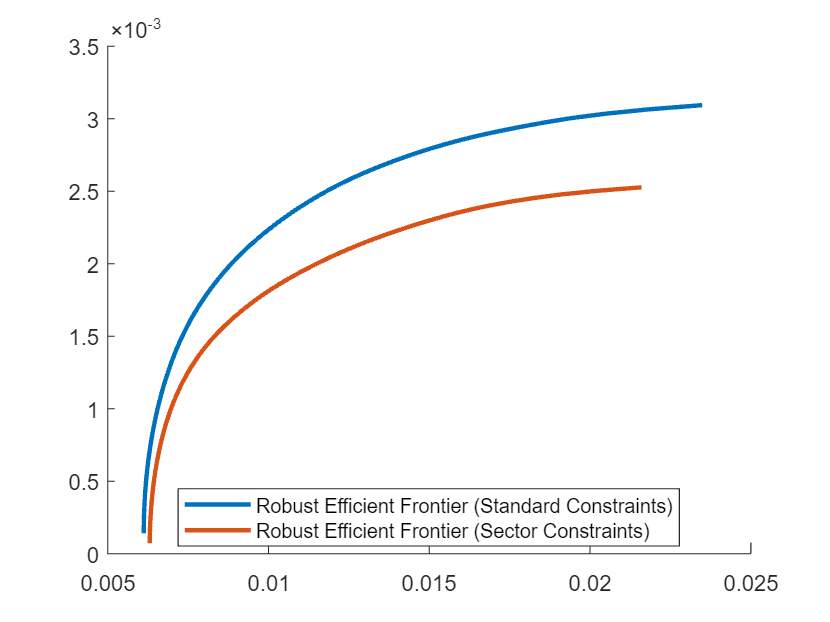

figure % create new figure
hold on
plot_legend = legend('Location', 'best'); % add legend and keep its handle

plot(robustFrontier_risk_standard, robustFrontier_ret_standard, 'LineWidth', 2); % plot frontier
plot_legend.String{end} = "Robust Efficient Frontier (Standard Constraints)";

plot(robustFrontier_risk_constrained, robustFrontier_ret_constrained, 'LineWidth', 2); % plot frontier
plot_legend.String{end} = "Robust Efficient Frontier (Sector Constraints)";

## Minimum variance portfolios of the robust efficient frontiers

We computed the minimum variance portfolio for both robust frontiers and we named them like follows:

- **Portfolio E: **minimum variance portfolio on the robust frontier with standard constraints

- **Portfolio F**: minimum variance portfolio on the robust frontier with sector constraints

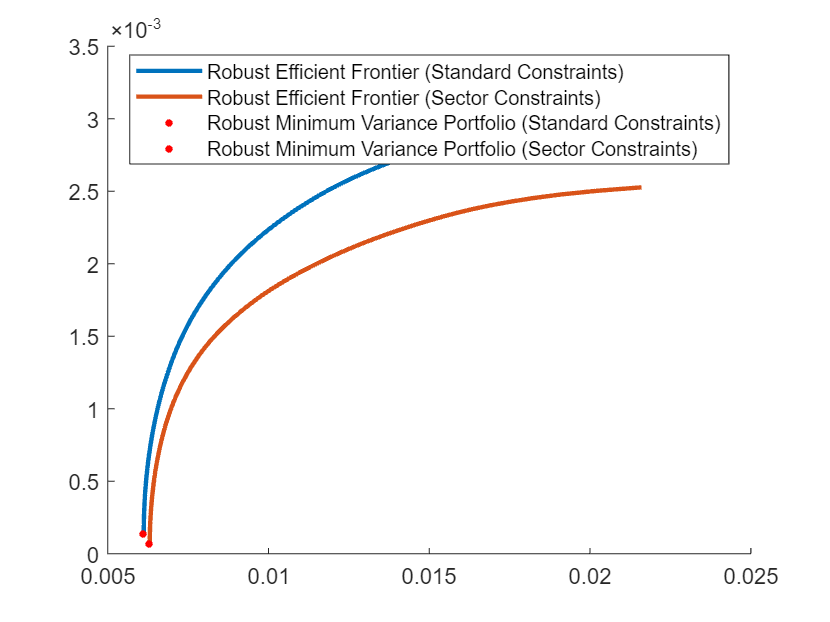

% find minimum variance portfolio
[~, min_var_idx_robust_standard] = min(robustFrontier_risk_standard);
portfolioE = pwgt_SimulationStandard(:,min_var_idx_robust_standard); % weights of the minimum variance portfolio

% plot minimum variance portfolio
plot(robustFrontier_risk_standard(min_var_idx_robust_standard), robustFrontier_ret_standard(min_var_idx_robust_standard), 'r.', 'MarkerSize', 10);
plot_legend.String{end} = "Robust Minimum Variance Portfolio (Standard Constraints)";

% find minimum variance portfolio
[~, min_var_idx_robust_constrained] = min(robustFrontier_risk_constrained);
portfolioF = pwgt_SimulationConstrained(:,min_var_idx_robust_constrained); % weights of the minimum variance portfolio

% plot minimum variance portfolio
plot(robustFrontier_risk_constrained(min_var_idx_robust_constrained), robustFrontier_ret_constrained(min_var_idx_robust_constrained), 'r.', 'MarkerSize', 10);
plot_legend.String{end} = "Robust Minimum Variance Portfolio (Sector Constraints)";

## Maximum Sharpe Ratio portfolios of the robust efficient frontiers

We computed the minimum variance portfolio for both robust frontiers and we named them like follows:

- **Portfolio G: **maximum Sharpe Ratio portfolio on the robust frontier with standard constraints

- **Portfolio H**: maximum Sharpe Ratio portfolio on the robust frontier with sector constraints

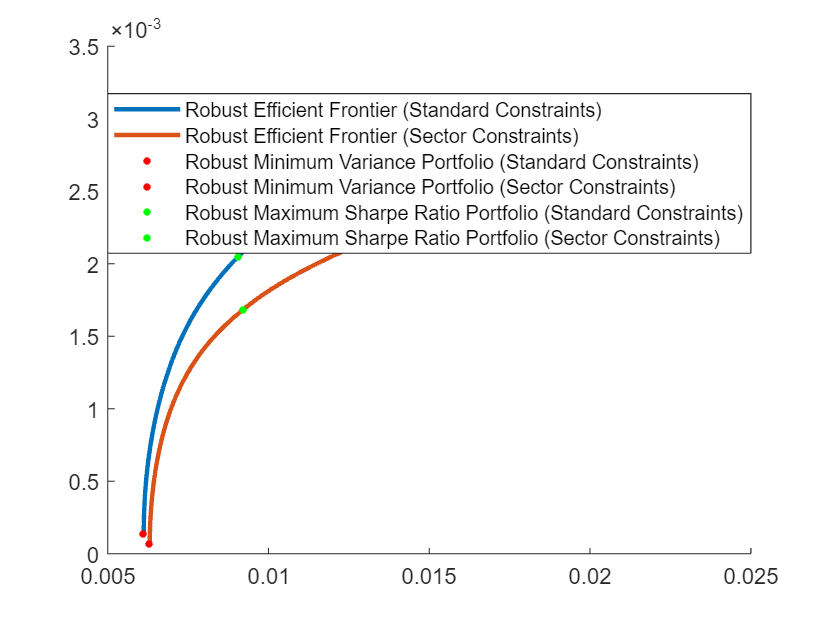

[~, max_sharpe_idx_robust_standard] = max(robustFrontier_ret_standard./robustFrontier_risk_standard);
portfolioG = pwgt_SimulationStandard(:,max_sharpe_idx_robust_standard); % weights of the maximum Sharpe Ratio portfolio

% plot maximum Sharpe Ratio portfolio
plot(robustFrontier_risk_standard(max_sharpe_idx_robust_standard), robustFrontier_ret_standard(max_sharpe_idx_robust_standard), 'g.', 'MarkerSize', 10);
plot_legend.String{end} = "Robust Maximum Sharpe Ratio Portfolio (Standard Constraints)";

[~, max_sharpe_idx_robust_constrained] = max(robustFrontier_ret_constrained./robustFrontier_risk_constrained);
portfolioH = pwgt_SimulationConstrained(:,max_sharpe_idx_robust_constrained); % weights of the maximum Sharpe Ratio portfolio

% plot maximum Sharpe Ratio portfolio
plot(robustFrontier_risk_constrained(max_sharpe_idx_robust_constrained), robustFrontier_ret_constrained(max_sharpe_idx_robust_constrained), 'g.', 'MarkerSize', 10);
plot_legend.String{end} = "Robust Maximum Sharpe Ratio Portfolio (Sector Constraints)";

## Exercise 4: Black-Litterman approach

We used the Black-Litterman approach under standard constraints to compute the efficient frontier incorporating the following views:

- The companies belonging to the sector “Consumer Staples” will have an annual return of 7%

- The companies belonging to the sector “Healthcare” will have an annual return of 3%

- The companies belonging to the sector “Communication Services” will outperform the companies belonging to the sector “Utilities” of 4%

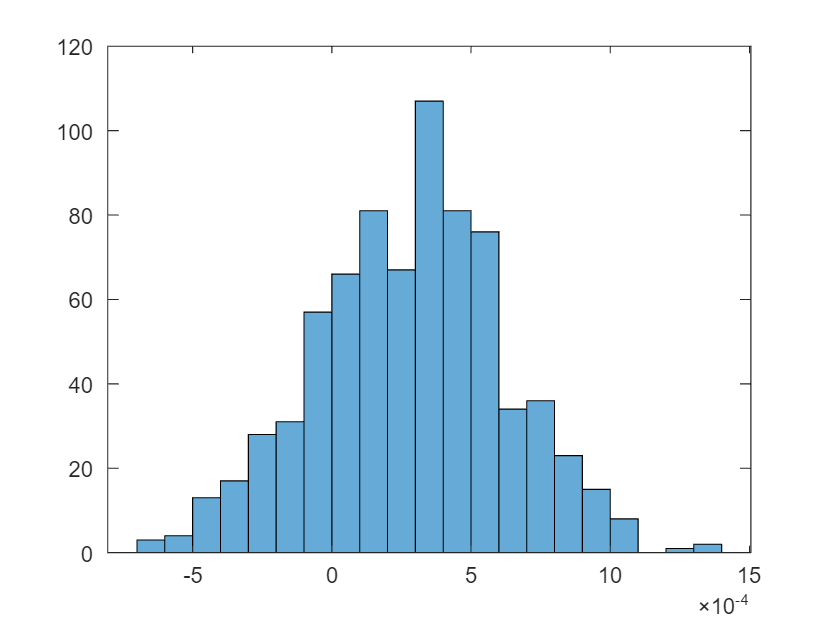

%Calculate returns and Covariance Matrix
Ret = Ret_array_A;
CovMatrix = cov(Ret);

%Building the views
tau = 1 / length(Ret);
v = 3; %total 3 views v = num views
P = zeros(v, N_assets);
q = zeros(v,1);
Omega = zeros(v);

%View1: companies belonging to the sector "Consumer Staples” will have an annual return of 7%
P(1, (table_sector.Sector == "Consumer Staples")') = 1;
q(1) = 0.07;

%View2: companies belonging to the sector “Healthcare” will have anannual return of 3%
P(2,(table_sector.Sector == "Health Care")') = 1;
q(2) = 0.03;

%View3: companies belonging to the sector "Communication Services" will outperform the companies belonging to the sector “Utilities” of 4%
P(3, (table_sector.Sector == "Communication Services")') = 1;
P(3, (table_sector.Sector == "Utilities")') = -1;
q(3) = 0.04;

%Compute Omega
Omega(1,1) = tau.*P(1,:)*CovMatrix*P(1,:)';
Omega(2,2) = tau.*P(2,:)*CovMatrix*P(2,:)';
Omega(3,3) = tau.*P(3,:)*CovMatrix*P(3,:)';

% From annual to daily view
bizyear2bizday = 1/252;
q = q * bizyear2bizday;
Omega = Omega*bizyear2bizday;

%Plot views distributions
figure()
X_views = mvnrnd(q, Omega, 750);
histogram(X_views(:,1))

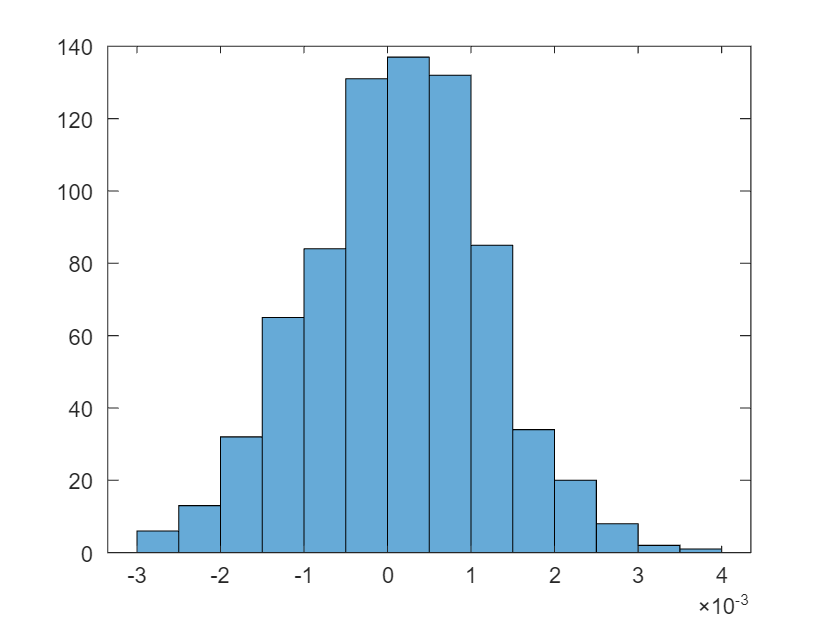


%Market implied return
wMkt = cap/sum(cap); %?
lambda = 1.2; % Assumption on risk propensity of the investor 
mu_mkt = lambda.*CovMatrix*wMkt;
C = tau.*CovMatrix; 

%Plot prior distribution
X = mvnrnd(mu_mkt,C,750);
histogram(X(:,1))


%Black Litterman
muBL = inv(inv(C)+ P'*inv(Omega)*P)*(P'*inv(Omega)*q + inv(C)*mu_mkt);
covBL = inv(P'*inv(Omega)*P + inv(C));
table(names_assets', mu_mkt*252, muBL*252, 'VariableNames', ["Asset Names", "Prior Belief of Exp Ret", "BL ExpRet"])

ans = 101×3 table
      Asset Names       Prior Belief of Exp Ret    BL ExpRet
    ________________    _______________________    _________

    {'AAPLUWEquity'}           0.034072             0.010804
    {'ABBVUNEquity'}           0.012766            0.0016267
    {'ABTUNEquity' }           0.020664            0.0025379
    {'ACNUNEquity' }           0.034395             0.010829
    {'ADBEUWEquity'}           0.036333             0.007543
    {'AIGUNEquity' }           0.043745             0.024981
    {'AMDUWEquity' }           0.054995             0.016396
    {'AMGNUWEquity'}           0.013746            0.0029407
    {'AMTUNEquity' }           0.018671            0.0056302
    {'AMZNUWEquity'}           0.039541             0.010112
    {'AVGOUWEquity'}           0.037184              0.01289
    {'AXPUNEquity' }           0.047008             0.026116
    {'BAUNEquity'  }     

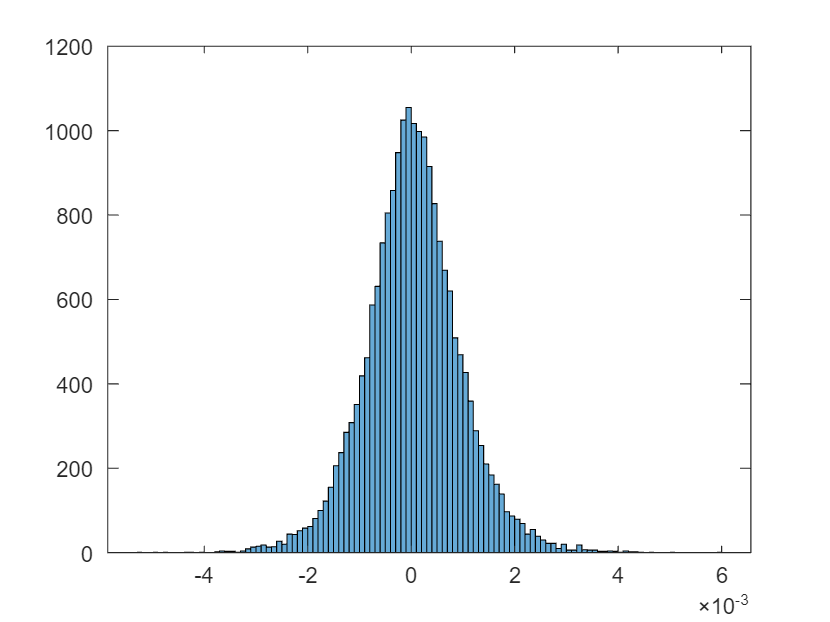


% Plot Distribution
figure()
XBL = mvnrnd(muBL, covBL, 200);
histogram(XBL)

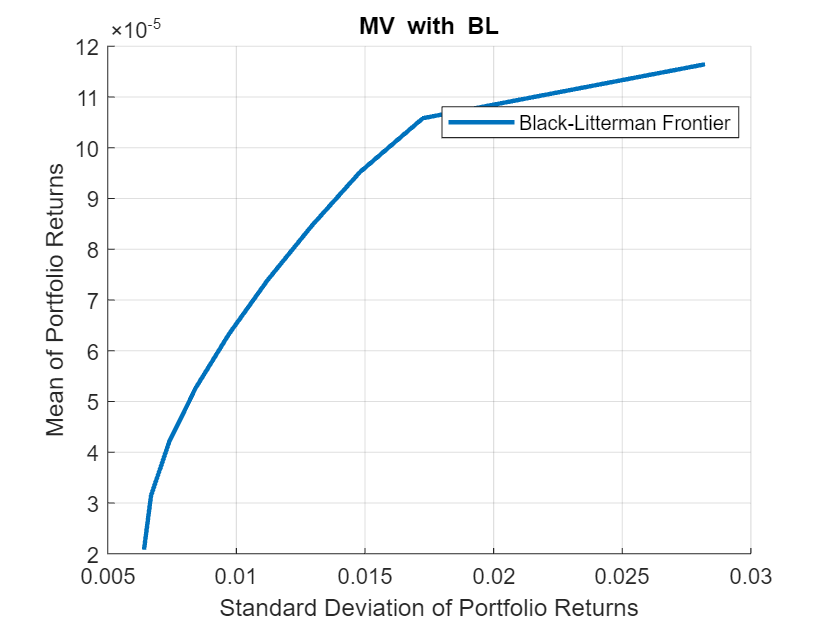


% Black Litterman Portfolio
portBL = Portfolio('NumAssets', N_assets, 'Name', 'MV with BL');
portBL = setAssetMoments(portBL, muBL, CovMatrix + covBL);
portBL = setDefaultConstraints(portBL);
% find minimum variance portfolio
pwgt_BL = estimateFrontier(portBL, N_assets);
[pfBL_risk, pfBL_ret] = estimatePortMoments(portBL,pwgt_BL);
[~, min_var_idx] = min(pfBL_risk);
portfolioI = pwgt_BL(:,min_var_idx);
% find max sharpe portfolio
[~, max_sharpe_idx_BL] = max(pfBL_ret./pfBL_risk); % in the original code, here's Port instead of PortBL
portfolioL = pwgt_BL(:,max_sharpe_idx_BL);

%Plot Frontier
figure; % create new figure
title('Portfolio Frontier with Black-Litterman Model')
plot_legend = legend('Location', 'best'); % add legend and keep its handle
hold on
plotFrontier(portBL)
plot_legend.String{end} = "Black-Litterman Frontier";

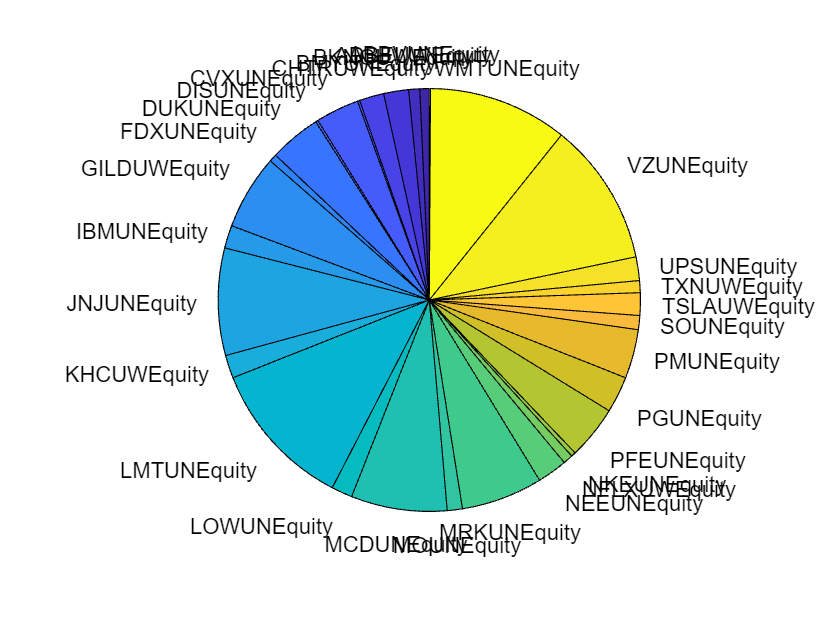


%Plot -> here we can add the pie of all ports computed above
figure()
idx_BL = portfolioI > 0.001;
pie(portfolioI(idx_BL), names_assets(idx_BL)); % A little messy, to adjust
title(portBL.Name, 'Position', [-0.05, 1.6, 0]);

## Exercice 5: Maximum diversified portfolio and maximum entropy portfolio

We impose the following constraints:

- All companies in the "Financials" sector must have a weight between 0.001. and 0.02.

- All companies in the "Industrials" sector must have a weight between 0.005 and 0.01

- Standard constraints

% set sector constraints
groupMatrix_F = (table_sector.Sector == "Financials")'; % extract the group Financials
groupMatrix_I = (table_sector.Sector == "Industrials")'; % extract the group Industrials
lowerbounds = 0.001*groupMatrix_F + 0.005*groupMatrix_I;
upperbounds = ones(length(N_assets),1)-0.98*groupMatrix_F-0.99*groupMatrix_I;

## Equally Weighted Portfolio

At this time we computed the Equally weighted portfolio to be used as a Benchmark against which to measure all other Portfolios.

wEW = 1/size(LogRet_array_A,2)*ones(N_assets,1);
RetPtfEW = wEW'*ExpLogRet_A';
VolaPtfEW = sqrt(wEW'*CovMatrix*wEW);

## Maximum Diversified Portfolio

We used the built-in *fmincon* function of matlab with the Diversification Ratio as our objective function to compute the maximum diversified portfolio, named **Portfolio M**.

Aeq = ones(1,N_assets);
beq = 1;
lb = lowerbounds;
ub = upperbounds;
x0 = zeros(N_assets,1);
x0(1,1) = 1;
options = optimoptions('fmincon','MaxFunctionEvaluations',1e5);

[w_DR, fval] = fmincon(@(x) -getDiversificationRatio(x, LogRet_array_A), x0, [], [], Aeq, beq, lb, ub, [], options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


MaxDR = -fval; 
portfolioM = w_DR > 1e-3; % Chiedere all'Angelini se possiamo farlo
portfolioM = portfolioM .* w_DR;

## Maximum Entropy portfolio

We used the built-in matlab function *fmincon* using the entropy as our objective function to find the maximum entropy portfolio.

We named it **Portfolio N**.

Aeq = ones(1,N_assets);
beq = 1;
lb = lowerbounds;
ub = upperbounds;
x0 = zeros(N_assets,1);
x0(1,1) = 1;
portfolioN = fmincon(@(x) -getEntropy(getVolContribution(x,LogRet_array_A)), x0, [], [], Aeq, beq, lb, ub, [], options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Exercise 6: Principal Component Analysis

We used the PCA approach to find which portfolios generate the most variance

k = 10; 
[factorLoading, factorRetn, latent] = pca(LogRet_array_A, 'NumComponents', k);

ToTVar = sum(latent);
ExplainedVar = latent(1:k)/ToTVar;

n_list = [1,2,3,4,5,6,7,8,9,10];
CumExplainedVar = zeros(1, size(n_list, 2));

for i = 1:size(n_list, 2)
    n = n_list(i);
    CumExplainedVar(1, i) = getCumulativeExplainedVar(latent, n);
end

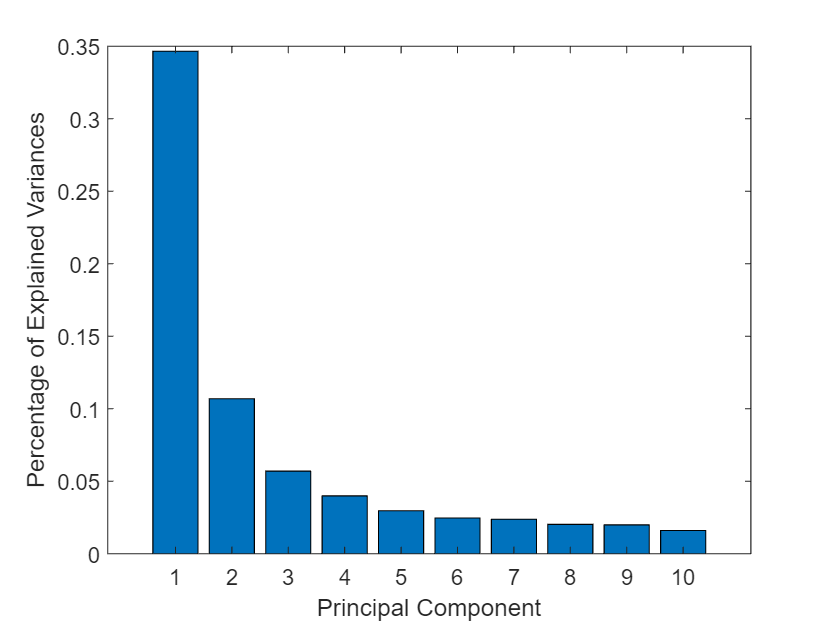

figure;
title('Percentage of Explained Variances for each principal component')
bar(n_list, ExplainedVar)
xlabel('Principal Component')
ylabel('Percentage of Explained Variances')


figure;
title('Total Percentage of Explained Variances for the first n-components')
plot(n_list, CumExplainedVar, 'm')
hold on
scatter(n_list, CumExplainedVar, 'm', 'filled')
grid on
xlabel('Total Number of Principal Components')
ylabel('Percentage of Explained Variances')

%reconstruct asset returns
covarFactor = cov(factorRetn);
reconReturn = factorRetn*factorLoading' + ExpLogRet_A;
unexplainedRetn = LogRet_array_A-reconReturn;

unexplainedCovar = diag(cov(unexplainedRetn));
D = diag(unexplainedCovar);

covarAsset = factorLoading*covarFactor*factorLoading'+D;

## Optimization return

We use the *fmincon* function which maximizes the expected returns and with the constraint that the volatility be less than 0.07 to find our portfolio.

We named this portfolio **Portfolio P**.

func = @(x) -ExpLogRet_A*x;

x0 = rand(size(LogRet_array_A,2),1);
x0 = x0./sum(x0);
lb = zeros(1,size(LogRet_array_A,2));
ub = ones(1,size(LogRet_array_A,2));
Aeq = ones(1,size(LogRet_array_A,2));
beq = 1;

nonlcon = @(x) freval(x,factorLoading,covarFactor,D);
[portfolioP, fval] = fmincon(func, x0, [], [], Aeq, beq, lb, ub,nonlcon, options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Exercise 7: Maximum Expected Shortfall - modified Sharpe Ratio

We modified the Sharpe Ratio to use the Expected Shortfall, calculated under Gaussian assumptions, as a metric of risk and found the maximum Sharpe Ratio Portfolio which we named **Portfolio Q**.

% Compute the VaR and ES of the assets

% ES computed with risk_free_rate = 0 and confidence_level = 0.05
fun = @(x) -modified_Sharpe(x, LogRet_array_A, 0, 0.05);
x0 = rand(size(LogRet_array_A,2),1);
x0 = x0./sum(x0);
lb = zeros(1,size(LogRet_array_A,2));
ub = ones(1,size(LogRet_array_A,2));
Aeq = ones(1,size(LogRet_array_A,2));
beq = 1;

[portfolioQ, fval] = fmincon(fun, x0, [], [], Aeq, beq, lb, ub, [], options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


## Exercise 8: Performance Metrics

For each Portfolio computed above we computed various metrics to gauge their performarce. In particular we computed the following for each:

- Annual Return

- Annual Volatility

- Sharpe Ratio

- Maximum DrawDown

- Kalmar Ratio

- Diversification Ratio

ret = array_assets_A(2:end,:)./array_assets_A(1:end-1,:);

Portfolios = [wEW, portfolioA, portfolioB, portfolioC, portfolioD, portfolioE, portfolioF, portfolioG, portfolioH, portfolioI, portfolioL, portfolioM, portfolioN, portfolioP, portfolioQ];
n_portfolios = size(Portfolios,2);
equity = [] ;
%Equity curve
for i = 1:n_portfolios
equity(:,i) = cumprod(ret*Portfolios(:,i));
equity(:,i) = 100.*equity(:,i)/equity(1,i);%force the equity to start from the same value
end
% Plot
dates_ = subsample_A.Time;
f = figure('Name','Equity first year');
title('Equity first year')
hold on
for i = 1:n_portfolios
plot(dates_(2:end,1), equity(:,i), 'LineWidth', 3)
legend('Equally Weighted Portfolio', 'A', 'B', 'C', 'D','E','F','G','H','I','L','M','N','P','Q')
xlabel('Date')
ylabel('Equity')
end
%
annRet = zeros(1,n_portfolios); annVol = zeros(1,n_portfolios); Sharpe = zeros(1,n_portfolios); MaxDD = zeros(1,n_portfolios); Calmar = zeros(1,n_portfolios); %preallocation for faster compiling
metrics = []; 
for i = 1:n_portfolios
[annRet(:,i), annVol(:,i), Sharpe(:,i), MaxDD(:,i), Calmar(:,i)] = getPerformanceMetrics(equity(:,i));
DivRatio(:,i) = getDiversificationRatio(Portfolios(:,i),ret);
metrics(:,i) = [annRet(:,i); annVol(:,i); Sharpe(:,i); MaxDD(:,i); Calmar(:,i);DivRatio(:,i)];
end
metrics_table = array2table(metrics,'VariableNames',["EW",'A', 'B', 'C', 'D','E','F','G','H','I','L','M','N','P','Q'],'RowNames',["AnnRet";"AnnVola";"SharpeRatio"; "Max DD";"CalmarRatio";"Diversification Ratio"])

metrics_table = 6×15 table
                                EW            A           B            C           D            E            F            G            H            I           L           M            N            P            Q    
                             _________    _________    ________    _________    ________    _________    _________    _________    _________    _________    ________    ________    __________    ________    _________

    AnnRet          

## Part B

Use prices from 12/05/2022 to 12/05/2023 to evaluate already computed portfolios

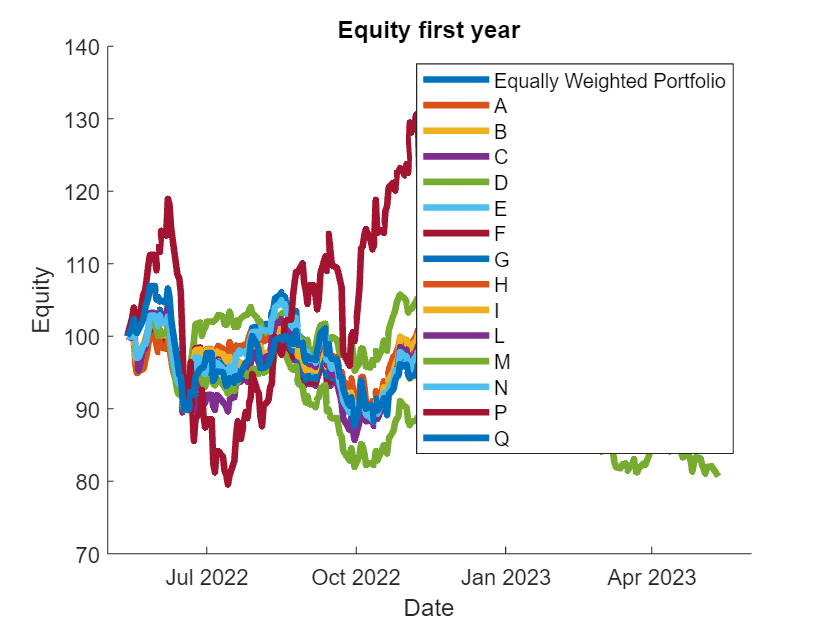

start_date_B = datetime('12/05/2022', 'InputFormat', 'dd/MM/yyyy');
end_date_B = datetime('12/05/2023', 'InputFormat', 'dd/MM/yyyy');
dates_range_B = timerange(start_date_B, end_date_B, "closed");
subsample_B = timetable_prices(dates_range_B, :);
array_assets_B = subsample_B.Variables; % array of prices
ret = array_assets_B(2:end,:)./array_assets_B(1:end-1,:);
equity = [];

%Equity curve
for i = 1:n_portfolios
equity(:,i) = cumprod(ret*Portfolios(:,i));
equity(:,i) = 100.*equity(:,i)/equity(1,i);%force the equity to start from the same value
end
% Plot
dates_ = subsample_B.Time;
f = figure('Name','Equity second year');
title('Equity first year')
hold on
for i = 1:n_portfolios
plot(dates_(2:end,1), equity(:,i), 'LineWidth', 3)
legend('Equally Weighted Portfolio', 'A', 'B', 'C', 'D','E','F','G','H','I','L','M','N','P','Q')
xlabel('Date')
ylabel('Equity')
end

%
annRet = zeros(1,n_portfolios); annVol = zeros(1,n_portfolios); Sharpe = zeros(1,n_portfolios); MaxDD = zeros(1,n_portfolios); Calmar = zeros(1,n_portfolios); %preallocation for faster compiling
metrics = []; 
for i = 1:n_portfolios
[annRet(:,i), annVol(:,i), Sharpe(:,i), MaxDD(:,i), Calmar(:,i)] = getPerformanceMetrics(equity(:,i));
DivRatio(:,i) = getDiversificationRatio(Portfolios(:,i),ret);
metrics(:,i) = [annRet(:,i); annVol(:,i); Sharpe(:,i); MaxDD(:,i); Calmar(:,i);DivRatio(:,i)];
end
metrics_table = array2table(metrics,'VariableNames',["EW",'A', 'B', 'C', 'D','E','F','G','H','I','L','M','N','P','Q'],'RowNames',["AnnRet";"AnnVola";"SharpeRatio"; "Max DD";"CalmarRatio";"Diversification Ratio"])

metrics_table = 6×15 table
                                EW           A            B            C             D            E            F             G             H            I            L           M            N            P            Q    
                             ________    _________    _________    __________    _________    _________    __________    __________    _________    _________    _________    ________    _________    _________    _________

    AnnRet